# **Overview**

This document provides an introduction to data wrangling and visualization in R. It contains sections marked as exercises. **Please complete these exercises prior to next Monday's class** and submit them on slack. In addition your homework for this Wednesday is to apply the knowledge gain from this tutorial *to your own data*. **By this Wednesday, post at least one plot about your data on slack using the skills learned in this tutorial.** You are encouraged to ask questions (and help others) on slack.

# **Version control + Live scripts**

Matlab provides an internal way to perform version control (logging and building a systematic repository of your files). To use it, download and install git on your computer. Get a free github.com or bitbucket.com account. You only have to do this once. After doing this, you can refer to the link: [https://www.mathworks.com/help/matlab/matlab_prog/clone-from-git-repository.html](https://www.mathworks.com/help/matlab/matlab_prog/clone-from-git-repository.html) for further instructions. Alternatively you can use github desktop or command line to personally manage version control instead of doing it internally via matlab.

Matlab live scripts which we use here are a great way to document and share your code. To create one just create a empty file with a *.mlx extension and open in matlab. They provide a way to provide easily executable code along with instructions in a convenient way. This is great for communication and teaching purposes but while debugging or writing project code, I personallly prefer writing the code as separate .m files. Try out what works best for you

# **Data wrangling**

Matlab has an inbuilt import engine to load the data in a nice and usable format. To use that simply right click the data file and select the 'Import Data' option which will parse standard files and give you the flexibility of choosing how your variables are loaded. You can also generate a script from the same window which you can run to do the process automatically. 

## Example data set

We will illustrate loading and summarizing data with the following data from an experiment with a 2AFC task. On each trial, subjects had to fixate on a fixation cross. The fixation cross was then replaced by a small small number, and subjects had to quickly answer whether they saw the number "3" or "8". Half of the trials displayed "3", half displayed "8". Within subject, the experiment manipulated two variables, the size of the number (1, 2, or 4) and whether the number was surrounded by four other numbers above, below, left, and right of it (hard) or not (easy). The presence of other numbers presented close to the target number is known to make recogntion of the target number harder---an effect known as "visual crowding". For each trial, the software recorded whether the subject's response was correct (1 = correct; 0 = incorrect) and the reaction time for the response (RT)

First we will load the data from the csv file and store the values in a table (I have generated a load script read_example_data.m by using a load data option as specified in the previous section). After reading the data we  can look at a brief summary of the contents of the table using the command summary

read_example_data;
summary(subjectdata);


Variables:

    size: 7200×1 double

        Values:

            Min       1     
            Median    2     
            Max       4     

    condition: 7200×1 categorical

        Values:

            easy    3600       
            hard    3600       

    trial: 7200×1 double

        Values:

            Min          1   
            Median    60.5   
            Max        120   

    subject: 7200×1 double

        Values:

            Min         1      
            Median    5.5      
            Max        10      

    correct: 7200×1 double

        Values:

            Min       0        
            Median    1        
            Max       1        

    RT: 7200×1 double

        Values:

            Min       24.979
            Median    212.79
            Max       1207.5



We can use functions on specific attributes of the subjectdata table to extract any particular quantity of interest we may need. For eg: the average proportion of correct responses across subjects which is the mean of the correct attribute

meanCorrect=mean(subjectdata.correct);
disp(['Average proportion of correct responses across subjects: ',num2str(meanCorrect)])

Average proportion of correct responses across subjects: 0.60625


We can also view conditional summaries, i.e. summary for a particular class of subjects or task categories. For eg: If we wanted the average proportion of correct responses if just for the stimuli of size 1, we can compute that by just computing the mean of responses where the size is 1.

meanCorrect_sz1=mean(subjectdata.correct(subjectdata.size==1));
disp(['Average proportion of correct responses across subjects for stimulus size 1: ',num2str(meanCorrect_sz1)])

Average proportion of correct responses across subjects for stimulus size 1: 0.49792


If we get new attributes which we want to append to a matlab table using a common attribute, we can use the command join. For eg. if we get the gender and age of the subjects tagged by their subject ID, we can use the join command to combine the information between the two tables.

table_new=[];
table_new.subject=[1:10]';
table_new.gender=categorical(...
    {'Female';'Male';'Male';'Female';'Female';'Male';'Female';'Male';'Female';'Male'});
table_new.age=[20;19;22;19;19;21;20;21;19;20];
table_new=struct2table(table_new);
summary(table_new);


Variables:

    subject: 10×1 double

        Values:

            Min         1      
            Median    5.5      
            Max        10      

    gender: 10×1 categorical

        Values:

            Female    5       
            Male      5       

    age: 10×1 double

        Values:

            Min       19   
            Median    20   
            Max       22   




subjectdata=join(subjectdata,table_new);
summary(subjectdata);


Variables:

    size: 7200×1 double

        Values:

            Min       1     
            Median    2     
            Max       4     

    condition: 7200×1 categorical

        Values:

            easy    3600       
            hard    3600       

    trial: 7200×1 double

        Values:

            Min          1   
            Median    60.5   
            Max        120   

    subject: 7200×1 double

        Values:

            Min         1      
            Median    5.5      
            Max        10      

    correct: 7200×1 double

        Values:

            Min       0        
            Median    1        
            Max       1        

    RT: 7200×1 double

        Values:

            Min       24.979
            Median    212.79
            Max       1207.5

    gender: 7200×1 categorical

        Values:

            Female    3600

## **Exercises**

How can we: 

-  View the entire data set? (just type out the variable name)

- Calculate the by-subject averages for all three number sizes? (mean)

-  Calculate the by-subject standard deviations around those averages? (std)

- Determine whether RTs were on average faster for correct, as compared to incorrect, trials? (conditional mean, see above)

-  Add a column for log-transformed RTs to the data set? (log)

- Remove the old column for raw RTs? (removevars)

- Sort the data by log-transformed reaction times? (sortrows)

# Data visualization

If we want to visualize certain attributes of the data, we can do that using the plot command. Let's say we want to plot the reaction times as a function of size for subject 1

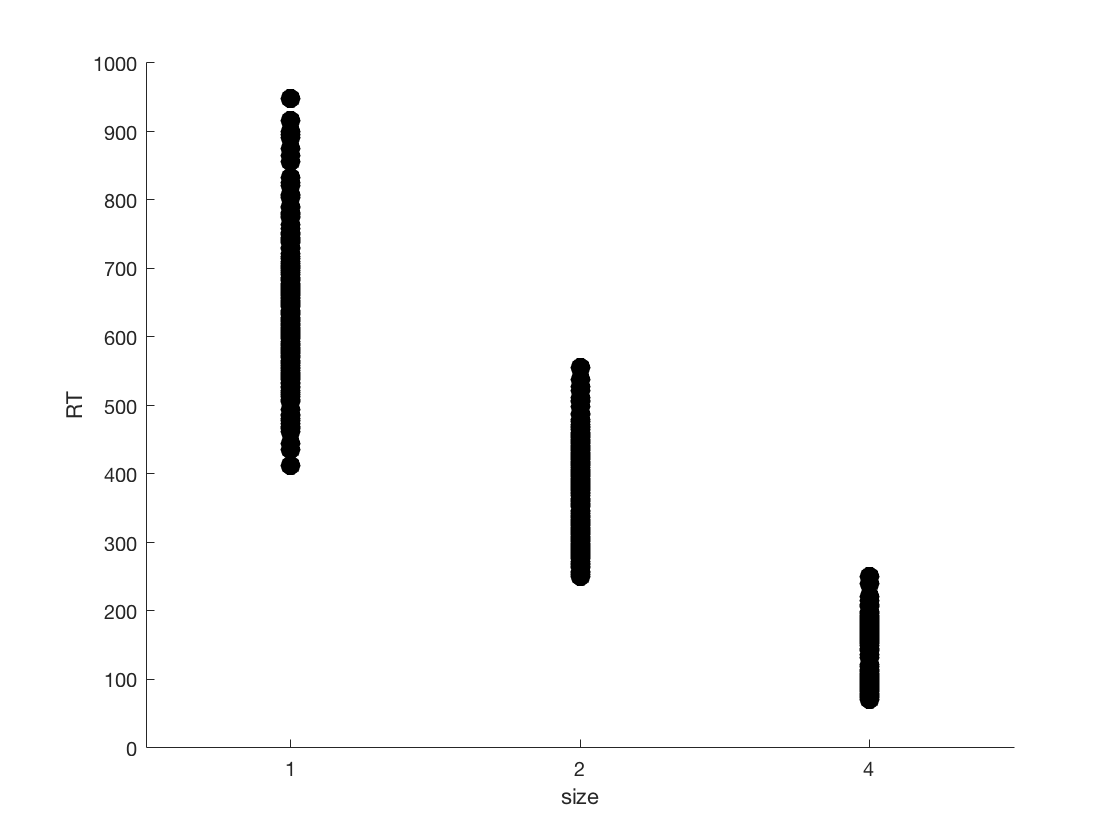

figure;
ids_plot=subjectdata.subject==1;
scatter(categorical(subjectdata.size(ids_plot)),subjectdata.RT(ids_plot),100,'k','filled');
xlabel('size');
ylabel('RT');

Notice that this plot is not particularly helpful! There is a lot of points and they are all overlaid, making it hard to get a clear idea of the data. One way we can improve this plot is to add transparency to the points. Another way is to jitter the points along the x-axis. Both approaches help convey information about the distribution of RTs at each number size, and sometimes—especially, when we have a lot of data—we might want to combine both approaches. For example, here’s the same plot with just transparency added. Since we have quite a bit of data, it still does not convey much information: 

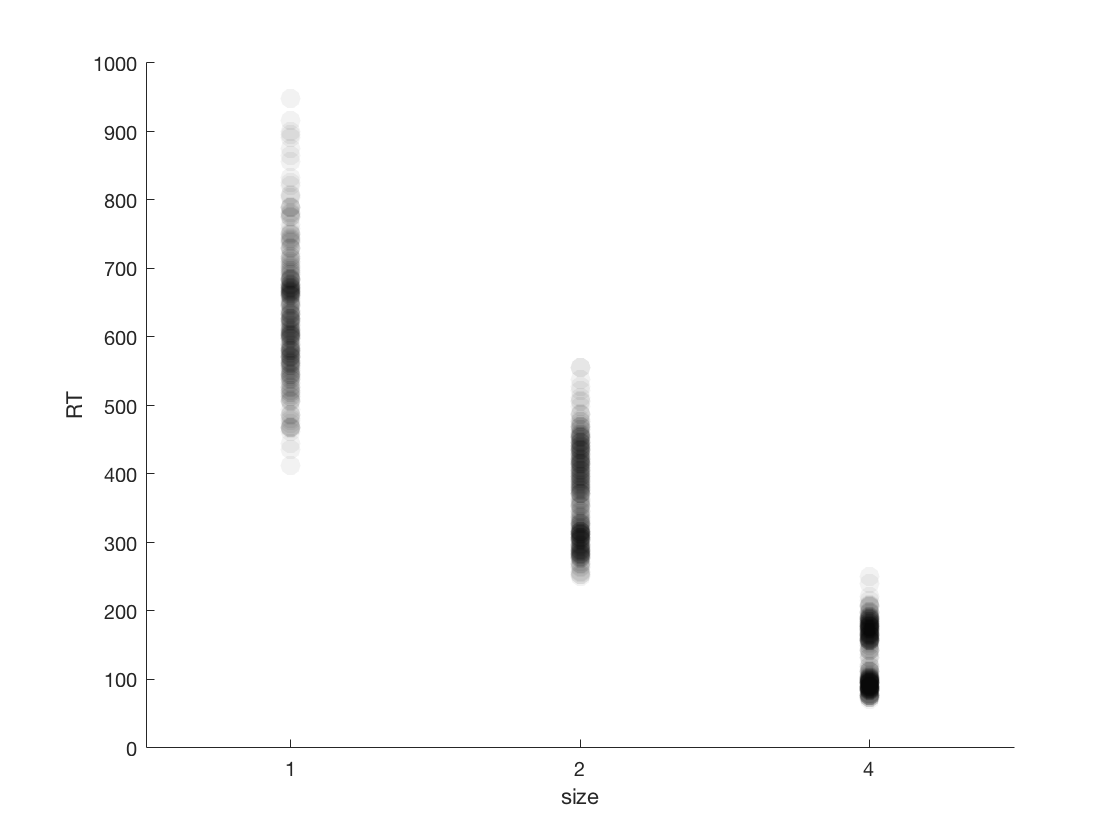

figure;
scatter1=scatter(categorical(subjectdata.size(ids_plot)),subjectdata.RT((ids_plot)),100,'k','filled');
alpha(scatter1,0.05)
xlabel('size');
ylabel('RT');

And here is the plot with some additional jitter added along the x-axis. Note that we intentionally avoid jitter along the y-axis: (why?)

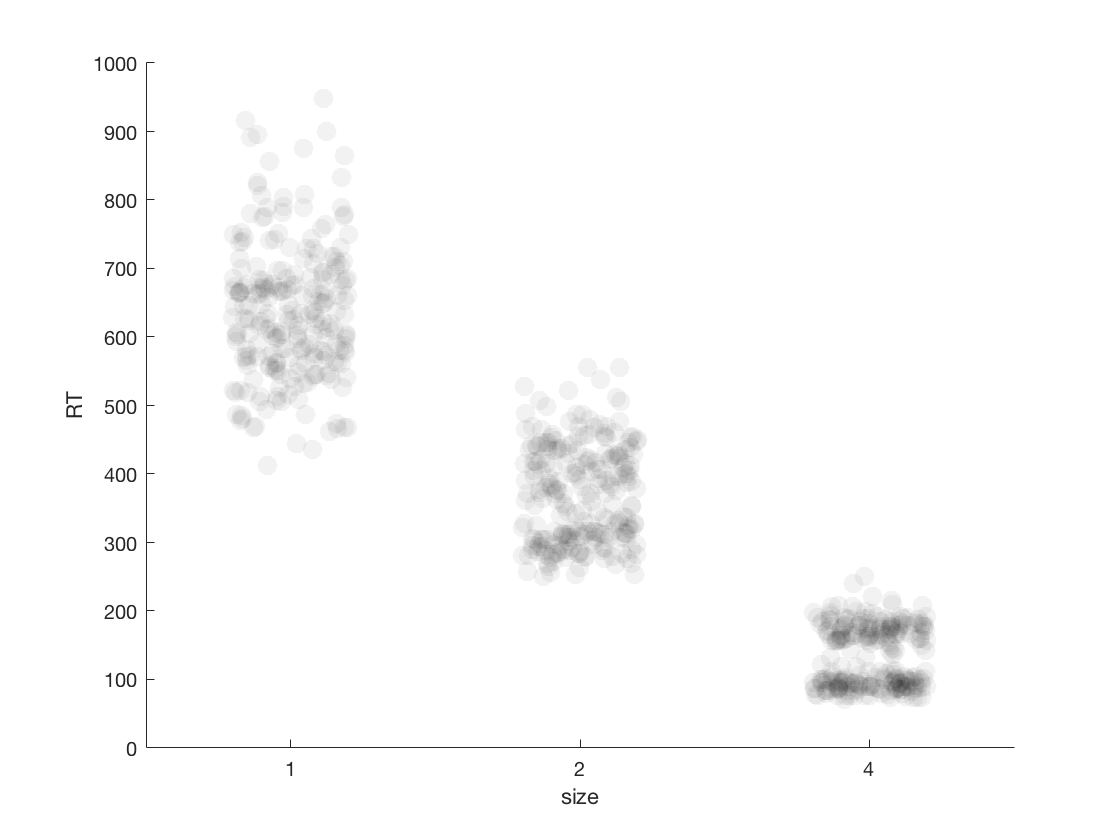

figure;
scatter1=scatter(categorical(subjectdata.size(ids_plot)),subjectdata.RT((ids_plot)),100,'k','filled','jitter','on','jitteramount',0.2);
alpha(scatter1,0.05)
xlabel('size');
ylabel('RT');

That’s much better already, giving us a much clearer idea of how the data is distributed! We are now in a position to think about how to include information about condition in this plot. There are a few ways to do this. For example, we could use di erent point shapes or colors for the easy and hard condition. Here, we do the latter: 

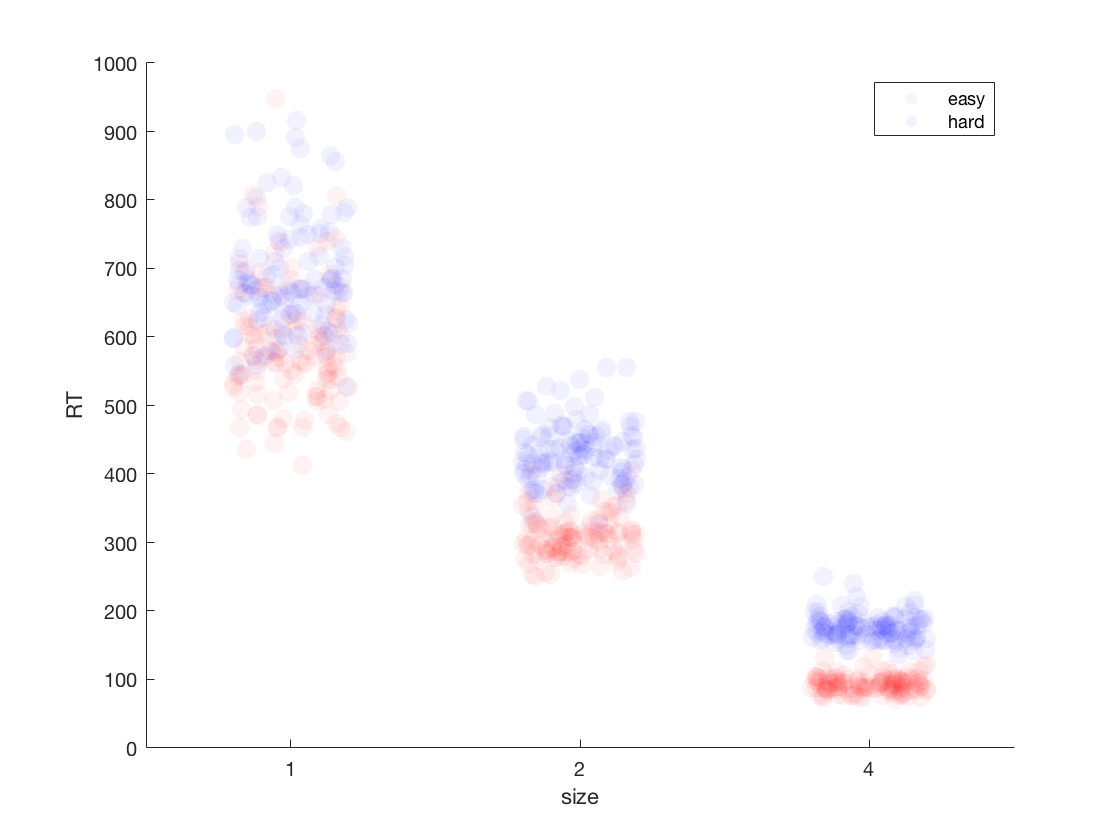

figure;
ids_plot_easy=(subjectdata.subject==1) & (subjectdata.condition=='easy');
ids_plot_hard=(subjectdata.subject==1) & (subjectdata.condition=='hard');

scatter1=scatter(categorical(subjectdata.size(ids_plot_easy)),subjectdata.RT((ids_plot_easy)),100,'r','filled','jitter','on','jitteramount',0.2);
hold on
scatter2=scatter(categorical(subjectdata.size(ids_plot_hard)),subjectdata.RT((ids_plot_hard)),100,'b','filled','jitter','on','jitteramount',0.2);

alpha(scatter1,0.05)
alpha(scatter2,0.05)
xlabel('size');
ylabel('RT');
legend({'easy','hard'});

Note the clear 'stripes' in the data

While it is often useful to see the raw data, this alone can be insufficient to communicate important aspects of the data. Specifically, we often are interested in whether the distributions of two conditions (e.g., the number size and easy vs. hard conditions) differ. The plots we have seen so far suggest that this might be the case, but we can’t be certain. In order to convey information about the distribution of our data, we often provide data summaries instead of—or in addition to—the raw data. Whenever possible, I would highly recommend to go with the “in addition to” option. There is a lof of value in seeing the raw data, as long as the overall tendencies we are interested in can also be recognized. 

Data can be summarized down to various levels of abstraction. For example, we can get the histogram or density of the data and plot that to show the distribution of the data points. This can be done using violin plots (https://github.com/bastibe/Violinplot-Matlab) as shown below

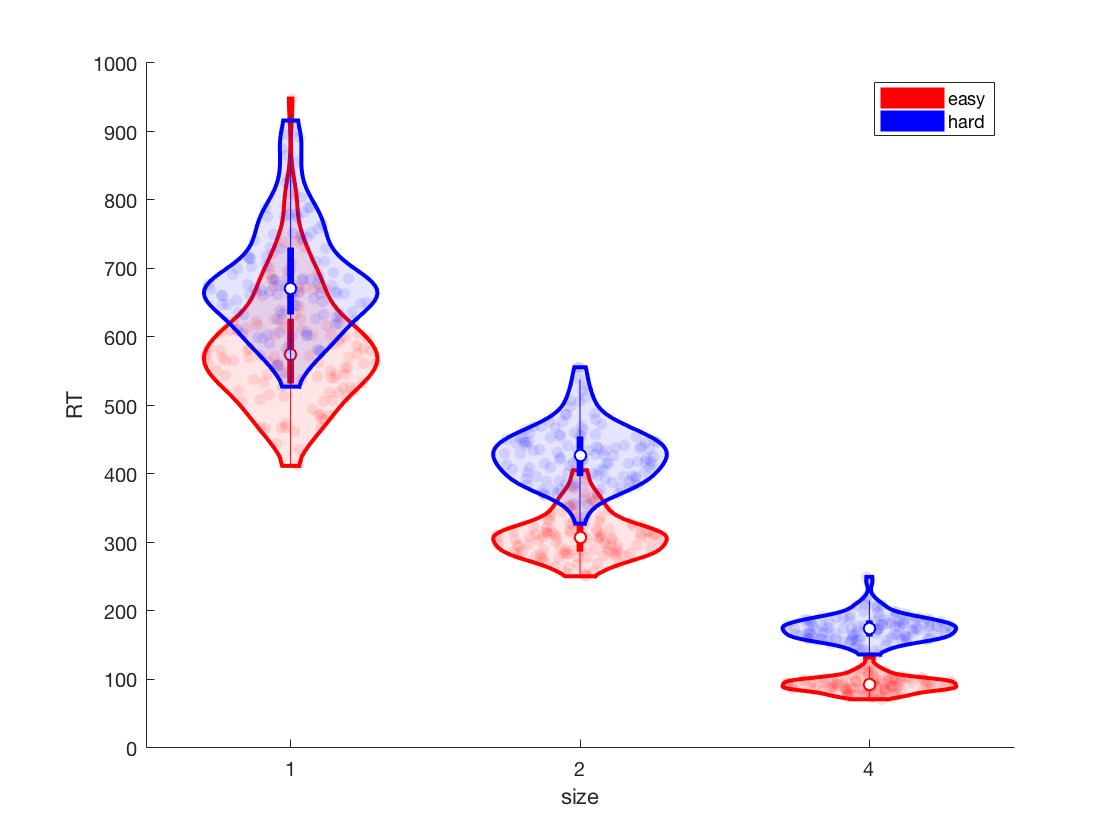

figure;
ids_plot_easy=(subjectdata.subject==1) & (subjectdata.condition=='easy');
ids_plot_hard=(subjectdata.subject==1) & (subjectdata.condition=='hard');



violin_easy=violinplot(subjectdata.RT((ids_plot_easy)),subjectdata.size(ids_plot_easy),'violincolor',[1,0,0],'showdata',true,'violinalpha',0.1,'edgecolor',[1,0,0],'boxcolor',[1,0,0]);
violin_hard=violinplot(subjectdata.RT((ids_plot_hard)),subjectdata.size(ids_plot_hard),'violincolor',[0,0,1],'showdata',true,'violinalpha',0.1,'edgecolor',[0,0,1],'boxcolor',[0,0,1]);

for i=1:3
    violin_easy(i).ViolinPlot.LineWidth=2;
    violin_hard(i).ViolinPlot.LineWidth=2;
end

xlabel('size');
ylabel('RT');
legend([violin_easy(1).ViolinPlot,violin_hard(1).ViolinPlot],{'easy','hard'});

Some researchers also like boxplots, which try to provide a high-level summary of the data while also providing **some** information about the general distribution of the data and any potential outliers. Boxplots tend to be plotted *instead* of the raw data since boxplots already contain any raw data that is not captured well by the summary they provide (the outlier points). The line in the center of the box provides the median of the data in that condition. The upper and lower end of the box indicate the "inter-quartile range (IQR) from the 25th to the 75th quantile of the outcome (you can use the command quantile() to get the quantiles yourself, if you want to compare them to what the plot provides). The whiskers (the lines below and above the box) extend to the largest and smallest value at most 1.5-times larger/smaller than the end of the box. Just as the height of the box provides a summary of the middle 50\% of the data (the IQR), the whiskeys give an idea of the distribution beyond that middle part. Any points outside of that range are plotted and are referred to as "outliers". Notably all outliers in the present case are high RT outliers, not low RT outliers. This is quite common for variables that have highly skewed distributions: RTs have a lower, but no upper bound. 

Finally, the notches (indentation on the sides of the box) provide the 95% confidence intervals around the means (CIs. We'll learn later **how CIs are obtained**, and what exactly they mean. For now, it suffices to say that (appropriately obtained) CIs are a critical visual component in plots when we want to know whether the means differ between conditions.

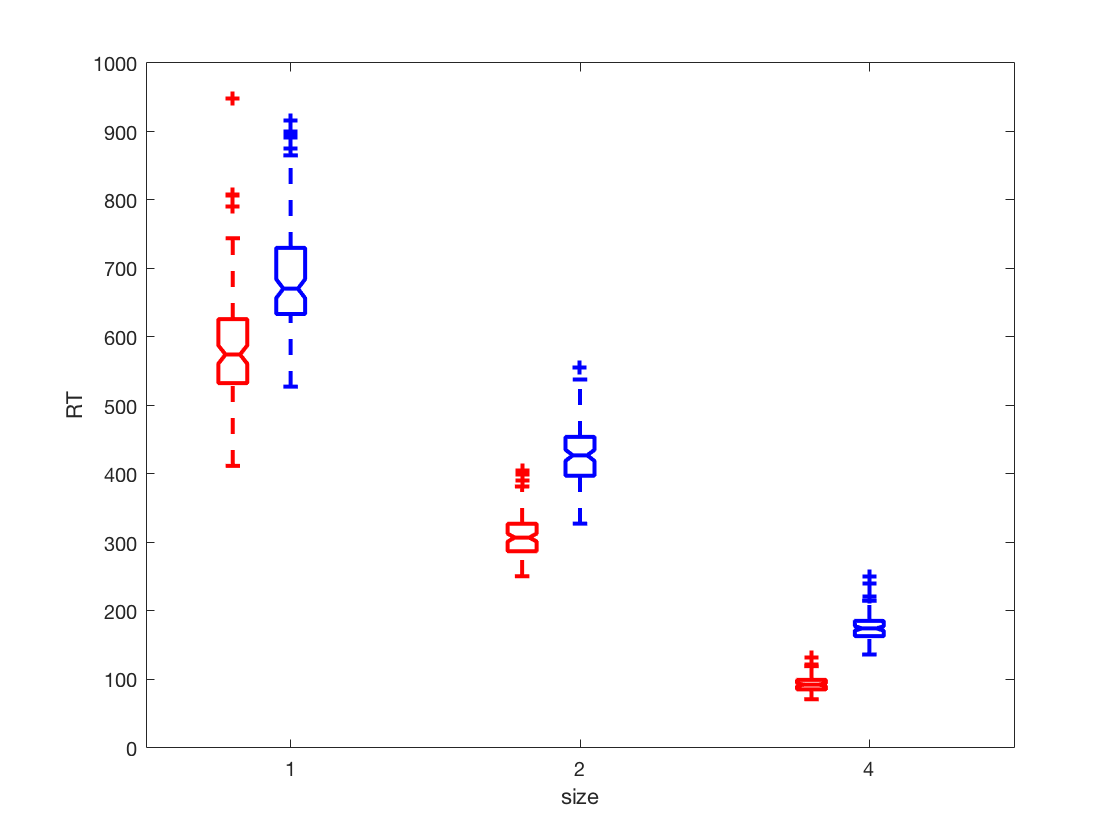

figure;
b_easy=boxplot(subjectdata.RT((ids_plot_easy)),subjectdata.size(ids_plot_easy),'positions',[0.9,1.9,2.9],'colors','r','notch','on','symbol','r+','widths',0.1);
hold on
b_hard=boxplot(subjectdata.RT((ids_plot_hard)),subjectdata.size(ids_plot_hard),'positions',[1.1,2.1,3.1],'Colors','b','notch','on','symbol','b+','widths',0.1);



set(b_easy,{'linew'},{2})
set(b_hard,{'linew'},{2})
xlabel('size');
ylabel('RT');
ylim([0,1000])

In publications, you will find that the data is often summarized even further into just the central tendency (mean) and its 95% CIs. Here we plot the mean and 95% CIs on top of the raw data. In this case, we have so much data that the CIs are very narrow and do not overlap indicating significance:

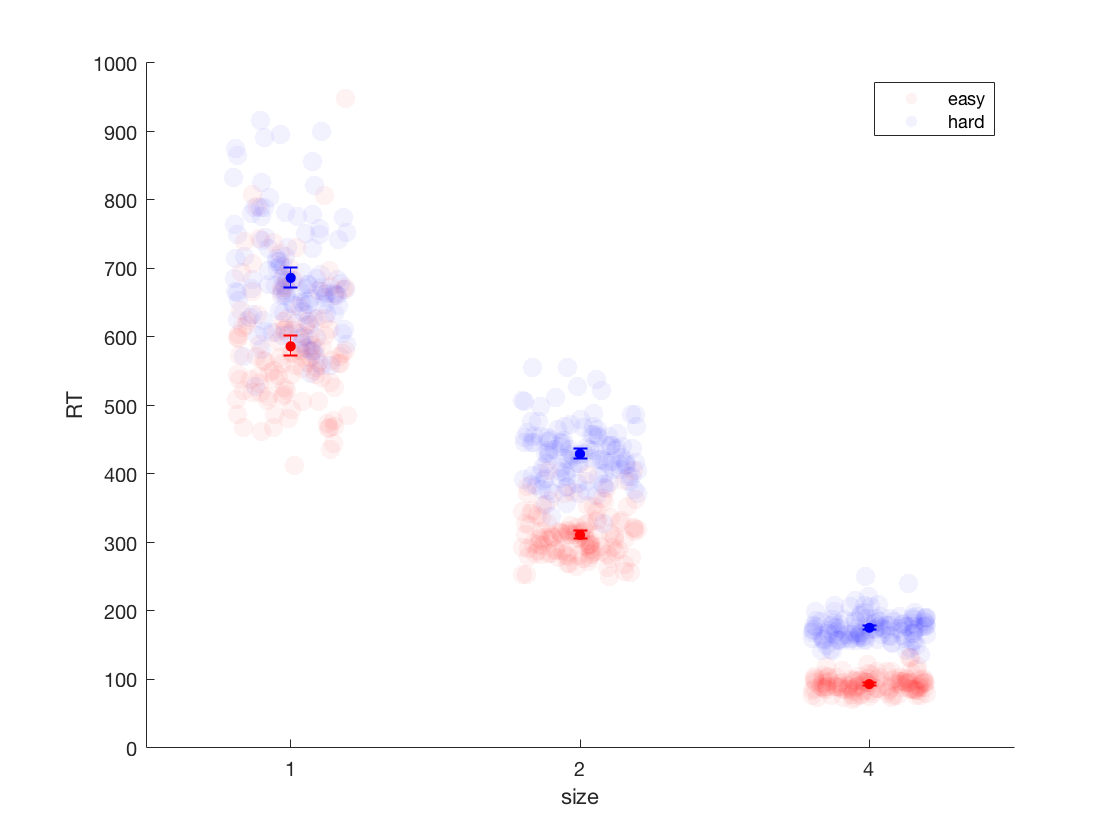

figure;
ids_plot_easy=(subjectdata.subject==1) & (subjectdata.condition=='easy');
ids_plot_hard=(subjectdata.subject==1) & (subjectdata.condition=='hard');

scatter1=scatter(categorical(subjectdata.size(ids_plot_easy)),subjectdata.RT((ids_plot_easy)),100,'r','filled','jitter','on','jitteramount',0.2);
hold on
scatter2=scatter(categorical(subjectdata.size(ids_plot_hard)),subjectdata.RT((ids_plot_hard)),100,'b','filled','jitter','on','jitteramount',0.2);
alpha(scatter1,0.05)
alpha(scatter2,0.05)

szs=[1,2,4];
for i=1:3
    ids_plot_easy_sz=(subjectdata.subject==1) & (subjectdata.condition=='easy') & (subjectdata.size==szs(i));
    ids_plot_hard_sz=(subjectdata.subject==1) & (subjectdata.condition=='hard') & (subjectdata.size==szs(i));
    mu_easy=mean(subjectdata.RT((ids_plot_easy_sz)));
    ci_easy=abs(bootci(10000,@mean,subjectdata.RT((ids_plot_easy_sz)))-mu_easy);
    mu_hard=mean(subjectdata.RT((ids_plot_hard_sz)));
    ci_hard=abs(bootci(10000,@mean,subjectdata.RT((ids_plot_hard_sz)))-mu_hard);
    errorbar(i,mu_easy,ci_easy(1),ci_easy(2),'r.','markersize',15);
    errorbar(i,mu_hard,ci_hard(1),ci_hard(2),'b.','markersize',15);
end



xlabel('size');
ylabel('RT');
legend({'easy','hard'});

## Plotting data from multiple subjects

So far we have plotted just one subject. Notice what happens when we update the scatter plot with the data from *all* subjects. There are now multiple 'stripes' visible in the data. Think about why that is the case. Any ideas?

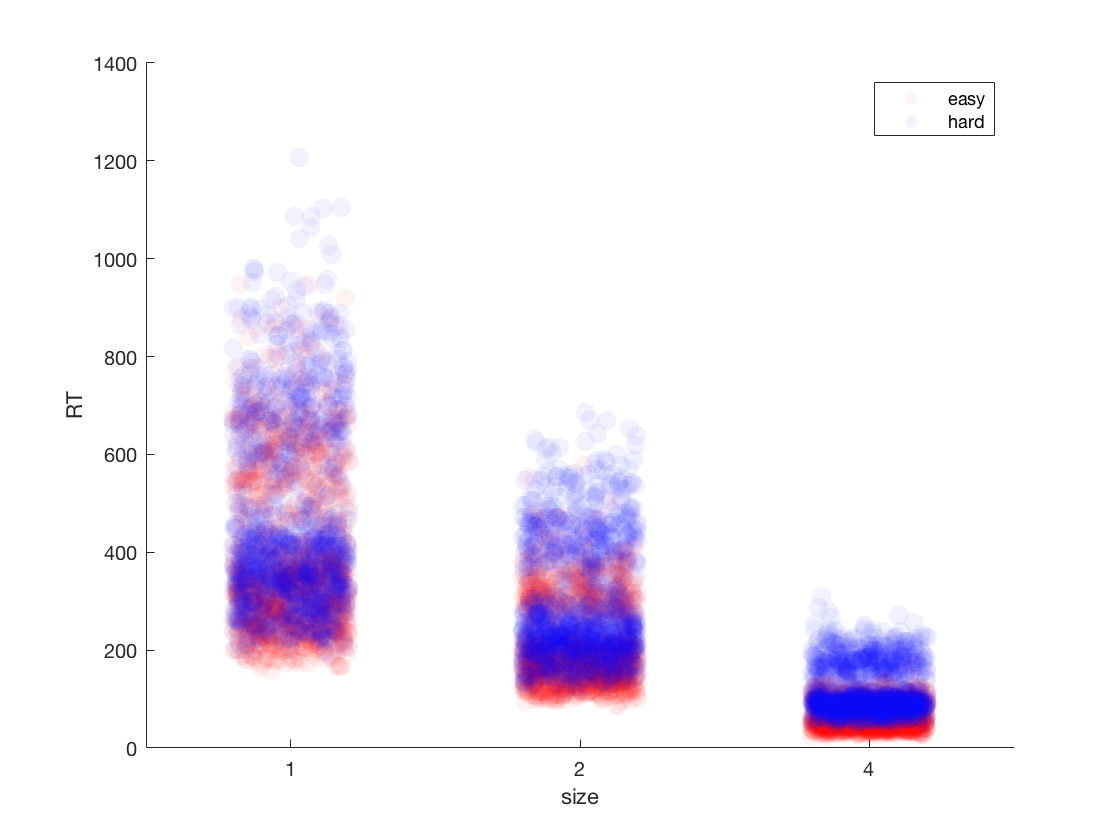

figure;
ids_plot_easy= (subjectdata.condition=='easy');
ids_plot_hard= (subjectdata.condition=='hard');

scatter1=scatter(categorical(subjectdata.size(ids_plot_easy)),subjectdata.RT((ids_plot_easy)),100,'r','filled','jitter','on','jitteramount',0.2);
hold on
scatter2=scatter(categorical(subjectdata.size(ids_plot_hard)),subjectdata.RT((ids_plot_hard)),100,'b','filled','jitter','on','jitteramount',0.2);

alpha(scatter1,0.05)
alpha(scatter2,0.05)
xlabel('size');
ylabel('RT');
legend({'easy','hard'});

Subjects differ from each other. This includes how fast they are overall, and might also include differences in how they are affected by the experimental conditions. This also means that the individual observations we are *not* independent of each other because the data points from the same subject resemble each other. We talk about "repeated measures" from the subject and call such data "repeated measures data". Another term that is used to refer to such data is *hierarchical* data or *hierarchically organized() data. Whenever we deal with such data, we need to be careful, for example, when we calculate CIs. We will return to that issue in our class on confidence intervals. For now, the next section focuses on how we can effectively visualize the data for all subjects without having to make many individual plots.

We can make separate panels in matlab when we want to show multiple plots that are related in some way. For eg., we can plot the individual subject responses in different panels and use the linkaxes command to tie together the axes of different plots (why?)

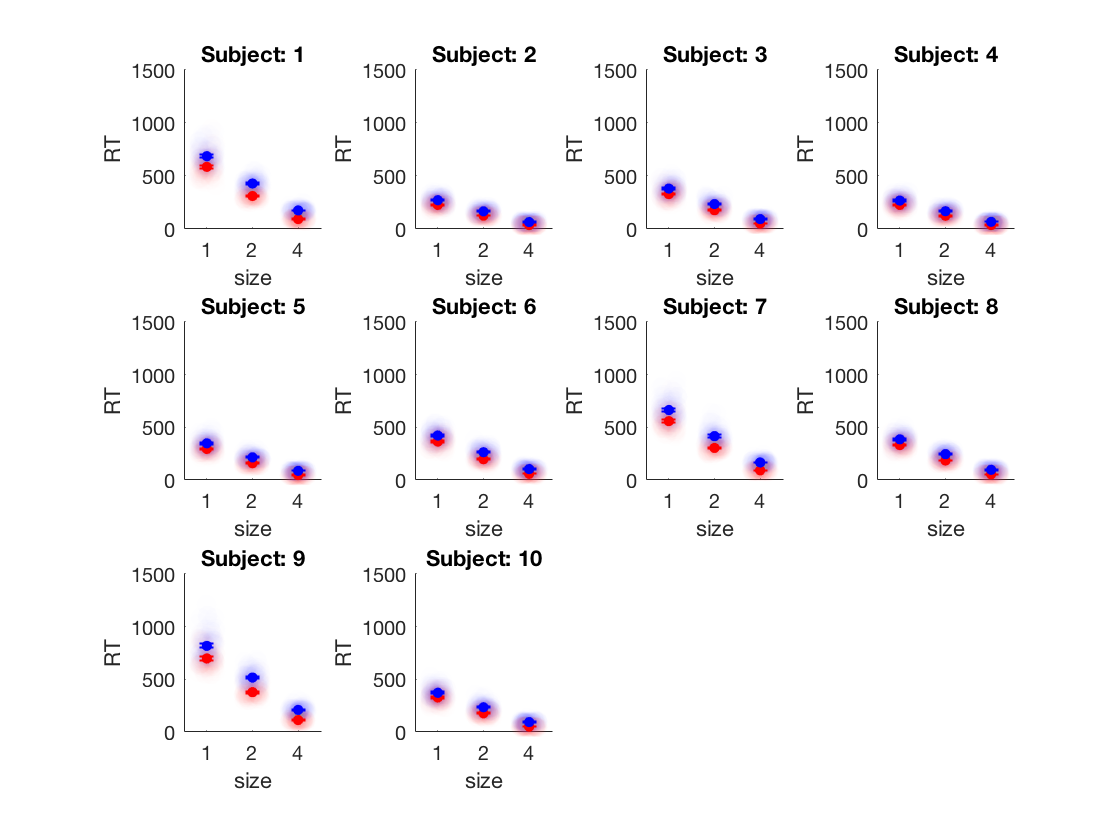

figure;
for k=1:10
    subplot(3,4,k)
    ids_plot_easy=(subjectdata.subject==k) & (subjectdata.condition=='easy');
    ids_plot_hard=(subjectdata.subject==k) & (subjectdata.condition=='hard');
    
    scatter1=scatter(categorical(subjectdata.size(ids_plot_easy)),subjectdata.RT((ids_plot_easy)),100,'r','filled','jitter','on','jitteramount',0.2);
    hold on
    scatter2=scatter(categorical(subjectdata.size(ids_plot_hard)),subjectdata.RT((ids_plot_hard)),100,'b','filled','jitter','on','jitteramount',0.2);
    alpha(scatter1,0.005)
    alpha(scatter2,0.005)
    
    szs=[1,2,4];
    for i=1:3
        ids_plot_easy_sz=(subjectdata.subject==k) & (subjectdata.condition=='easy') & (subjectdata.size==szs(i));
        ids_plot_hard_sz=(subjectdata.subject==k) & (subjectdata.condition=='hard') & (subjectdata.size==szs(i));
        mu_easy=mean(subjectdata.RT((ids_plot_easy_sz)));
        ci_easy=abs(bootci(10000,@mean,subjectdata.RT((ids_plot_easy_sz)))-mu_easy);
        mu_hard=mean(subjectdata.RT((ids_plot_hard_sz)));
        ci_hard=abs(bootci(10000,@mean,subjectdata.RT((ids_plot_hard_sz)))-mu_hard);
        errorbar(i,mu_easy,ci_easy(1),ci_easy(2),'r.','markersize',15);
        errorbar(i,mu_hard,ci_hard(1),ci_hard(2),'b.','markersize',15);
    end
    
    
    
    xlabel('size');
    ylabel('RT');
    title(['Subject: ',num2str(k)]);
    drawnow
end
linkaxes

or we can separate the responses by correct/incorrect choice

figure;
sub_ids=randperm(10);
sub_ids=sub_ids(1:6);
for l=1:2
for k=1:6
    subplot(2,6,6*(l-1)+k)
    ids_plot_easy=(subjectdata.subject==sub_ids(k)) & (subjectdata.condition=='easy') & (subjectdata.correct==(l-1));
    ids_plot_hard=(subjectdata.subject==sub_ids(k)) & (subjectdata.condition=='hard') & (subjectdata.correct==(l-1));
    
    scatter1=scatter(categorical(subjectdata.size(ids_plot_easy)),subjectdata.RT((ids_plot_easy)),100,'r','filled','jitter','on','jitteramount',0.2);
    hold on
    scatter2=scatter(categorical(subjectdata.size(ids_plot_hard)),subjectdata.RT((ids_plot_hard)),100,'b','filled','jitter','on','jitteramount',0.2);
    alpha(scatter1,0.005)
    alpha(scatter2,0.005)
    
    szs=[1,2,4];
    for i=1:3
        ids_plot_easy_sz=(subjectdata.subject==sub_ids(k)) & (subjectdata.condition=='easy') & (subjectdata.size==szs(i)) & (subjectdata.correct==(l-1));
        ids_plot_hard_sz=(subjectdata.subject==sub_ids(k)) & (subjectdata.condition=='hard') & (subjectdata.size==szs(i)) & (subjectdata.correct==(l-1));
        mu_easy=mean(subjectdata.RT((ids_plot_easy_sz)));
        ci_easy=abs(bootci(10000,@mean,subjectdata.RT((ids_plot_easy_sz)))-mu_easy);
        mu_hard=mean(subjectdata.RT((ids_plot_hard_sz)));
        ci_hard=abs(bootci(10000,@mean,subjectdata.RT((ids_plot_hard_sz)))-mu_hard);
        errorbar(i,mu_easy,ci_easy(1),ci_easy(2),'r.','markersize',15);
        errorbar(i,mu_hard,ci_hard(1),ci_hard(2),'b.','markersize',15);
    end
    
    
    
    xlabel('size');
    ylabel({['Correct: ',num2str(l-1)],'RT'});
    title([num2str(sub_ids(k))]);
    drawnow
end
end
linkaxes

## **Scales and coordinate systems**

Sometimes we don't want to see all of the data, or we want to zoom into some ranges of our data. We can do so by explicitly specifying the x- and y-limits of our coordinate system using ylim (or xlim for limiting the x axis). Here we limit the axes to show reaction times between 100 and 900.

figure;
ids_plot_easy= (subjectdata.condition=='easy');
ids_plot_hard= (subjectdata.condition=='hard');



violin_easy=violinplot(subjectdata.RT((ids_plot_easy)),subjectdata.size(ids_plot_easy),'violincolor',[1,0,0],'showdata',true,'violinalpha',0.1,'edgecolor',[1,0,0],'boxcolor',[1,0,0]);
violin_hard=violinplot(subjectdata.RT((ids_plot_hard)),subjectdata.size(ids_plot_hard),'violincolor',[0,0,1],'showdata',true,'violinalpha',0.1,'edgecolor',[0,0,1],'boxcolor',[0,0,1]);

for i=1:3
    violin_easy(i).ViolinPlot.LineWidth=2;
    violin_hard(i).ViolinPlot.LineWidth=2;
end

xlabel('size');
ylabel('RT');
ylim([100,900])
legend([violin_easy(1).ViolinPlot,violin_hard(1).ViolinPlot],{'easy','hard'});

Note that this zooms into parts of our data without excluding any data (e.g., from the calculation of the violins, which have the same shape as above). If we want to exclude data, transform data or in other ways change the way the aesthetical mappings are interpreted, this is achieved through setting conditions on the data that goes into the violin plot. For eg: We can choose to just have the reaction times between 100 and 900.

figure;
ids_plot_easy= (subjectdata.condition=='easy') & subjectdata.RT>100 & subjectdata.RT<900;
ids_plot_hard= (subjectdata.condition=='hard') & subjectdata.RT>100 & subjectdata.RT<900;



violin_easy=violinplot(subjectdata.RT((ids_plot_easy)),subjectdata.size(ids_plot_easy),'violincolor',[1,0,0],'showdata',true,'violinalpha',0.1,'edgecolor',[1,0,0],'boxcolor',[1,0,0]);
violin_hard=violinplot(subjectdata.RT((ids_plot_hard)),subjectdata.size(ids_plot_hard),'violincolor',[0,0,1],'showdata',true,'violinalpha',0.1,'edgecolor',[0,0,1],'boxcolor',[0,0,1]);

for i=1:3
    violin_easy(i).ViolinPlot.LineWidth=2;
    violin_hard(i).ViolinPlot.LineWidth=2;
end

xlabel('size');
ylabel('RT');
ylim([0,1000])
legend([violin_easy(1).ViolinPlot,violin_hard(1).ViolinPlot],{'easy','hard'});

For example, since reaction times often have distributions that are more lognormal, rather than normal, let's update our original plot to use a log-transformed y-axis.

figure;
ids_plot_easy= (subjectdata.condition=='easy');
ids_plot_hard= (subjectdata.condition=='hard');



violin_easy=violinplot(subjectdata.RT((ids_plot_easy)),subjectdata.size(ids_plot_easy),'violincolor',[1,0,0],'showdata',true,'violinalpha',0.1,'edgecolor',[1,0,0],'boxcolor',[1,0,0]);
violin_hard=violinplot(subjectdata.RT((ids_plot_hard)),subjectdata.size(ids_plot_hard),'violincolor',[0,0,1],'showdata',true,'violinalpha',0.1,'edgecolor',[0,0,1],'boxcolor',[0,0,1]);

for i=1:3
    violin_easy(i).ViolinPlot.LineWidth=2;
    violin_hard(i).ViolinPlot.LineWidth=2;
end

xlabel('size');
ylabel('RT');
yticks([30,100,300,1000])

set(gca, 'YScale', 'log')

legend([violin_easy(1).ViolinPlot,violin_hard(1).ViolinPlot],{'easy','hard'});

## Exercises

- Plot a histogram of the RTs by number size. Make on version where you plots the histograms in different subpplots, and another version where you have only one plot and use color to distinguish between number sizes. (hist,ksdensity)

- Plot the average proportion of correct answers by number size

- Do the same, but first average by subject and number size, and then plot the average (and confidence interval) of those by-subject averages of correct responses

- Try to make a pie chart that shows the proportion correct for the three number sizes (pie)